# **Estimating Option-Implied Probability Distributions for Asset Pricing**

This Live Script contains the code for the technical article [*Estimating Option-Implied Probability Distributions for Asset Pricing*](https://uk.mathworks.com/company/newsletters/articles/estimating-option-implied-probability-distributions-for-asset-pricing.html)*.*

*Copyright 2015-2023 The MathWorks, Inc.*

**Notation**

In this example, we use the following notation for option and asset-related quantities.

- $K$ - strike price of the option (expressed in currency units).

- $C$ - option call price (expressed in currency units).

- $P$ - option put price (expressed in currency units).

- $S$ - price of the underlying asset (expressed in currency units).

- $T$ - option expiry time (years).

- $r_f$ - risk-free interest rate, expressed as a decimal number in the range [0, 1].

- $\sigma$ - volatility of the underlying asset, expressed as a decimal number in the range [0, 1].

## Load the hypothetical option data and associated parameters.

Suppose that we observe, from the market, the following option prices for an underlying asset. See the function [`generateSampleOptionData`](matlab: edit generateSampleOptionData) for details on how the simulated data is created.

D = generateSampleOptionData();
disp(head(D))

      K          C            P         T       rf       S 
    _____    _________    _________    ____    _____    ___

       98        2.123     0.001095    0.25    0.005    100
     98.8       1.3259     0.001774    0.25    0.005    100
     99.6      0.56518      0.03936    0.25    0.005    100
    100.4      0.09531       0.3691    0.25    0.005    100
    101.2    0.0040725       1.0785    0.25    0.005    100
      102    0.0013436       1.8737    0.25    0.005    100
       98       2.3683    0.0010833    0.75    0.005    100
     98.8       1.5831     0.014489    0.75    0.005    100



We note that we may have only a small number of observed $(K, C)$ or $(K, P)$ pairs for each distinct expiry time, as is typical with real market data.

## Compute the implied volatility from the market data.

To do this, we use the Financial Toolbox function [`blsimpv`](matlab: doc blsimpv) to compute the implied volatilities from the available market data. This function uses an iterative approach via comparison with prices from the Black-Scholes model.

D.SigmaCall = blsimpv(D.S, D.K, D.rf, D.T, D.C, [], [], [], "call");
D.SigmaPut = blsimpv(D.S, D.K, D.rf, D.T, D.P, [], [], [], "put");

## Visualize the market data in strike-volatility space.

We stratify the chart by time to expiry since we are interested in the $(K, \sigma)$ pairs for each distinct value of $T$.

First, plot the option call prices.

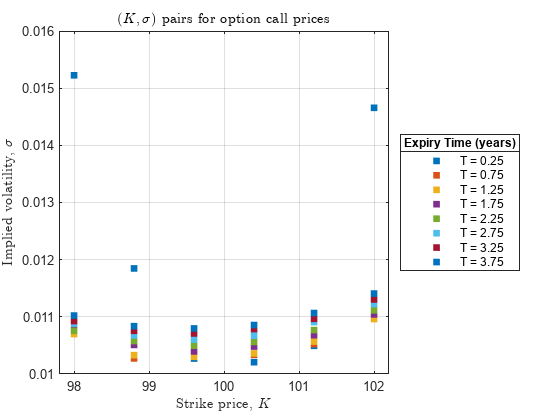

figure
gscatter(D.K, D.SigmaCall, D.T)
xlabel("Strike price, $K$", "Interpreter", "latex")
ylabel("Implied volatility, $\sigma$", "Interpreter", "latex")
title("$(K, \sigma)$ pairs for option call prices", "Interpreter", "latex")
grid on
T0 = unique(D.T);
legText = "T = " + num2str(T0);
lg = legend(legText, "Location", "eastoutside");
title(lg, "Expiry Time (years)")
hold on

Store the plot colors for future use.

ax = gca;
cols = flipud(vertcat(ax.Children.Color));

Repeat for the option put prices.

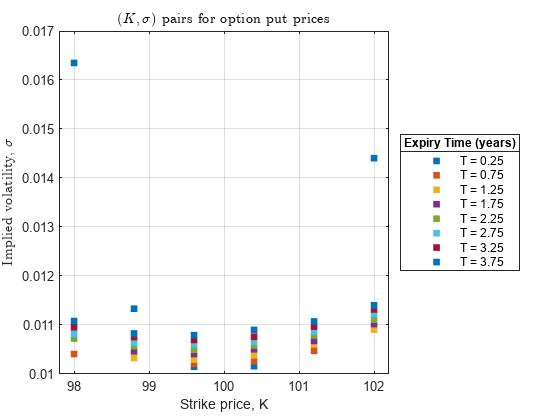

figure
gscatter(D.K, D.SigmaPut, D.T)
xlabel("Strike price, K")
ylabel("Implied volatility, $\sigma$", "Interpreter", "latex")
title("$(K, \sigma)$ pairs for option put prices", "Interpreter", "latex")
grid on
lg = legend(legText, "Location", "eastoutside");
title(lg, "Expiry Time (years)")
hold on

## Use interpolation to estimate more sample points.

In order to produce a reasonable approximation to the strike price probability density functions, we need more data points. One approach is to use cubic interpolation in $(K, \sigma)$ space to produce more sample points. We do this for each distinct expiry time. See the function [`interp1`](matlab: doc interp1) for more details of the different interpolation options.

Define sample strike prices for the interpolation.

extrapThresh = 0.01;
fineK = linspace(min(D.K)-extrapThresh, max(D.K)+extrapThresh, 500).';

Preallocate space for the results.

sigmaCallInterp = NaN(numel(fineK), numel(T0)); 
sigmaPutInterp = sigmaCallInterp;

Iterate over each unique expiry time.

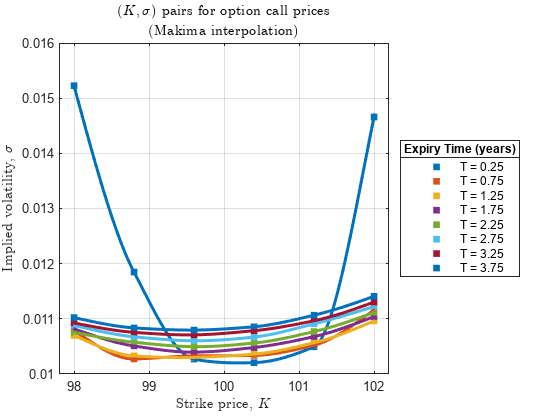

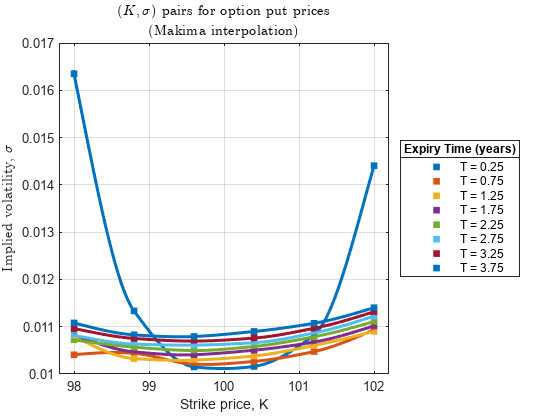

for k = 1:numel(T0)
    
    % Extract strike/sigma values for each value of T.
    idx = D.T == T0(k);
    tempK = D.K(idx);
    tempSigCall = D.SigmaCall(idx);
    tempSigPut = D.SigmaPut(idx);
    
    % Store the results.
    sigmaCallInterp(:, k) = interp1(tempK, tempSigCall, fineK, "makima", "extrap");
    sigmaPutInterp(:, k) = interp1(tempK, tempSigPut, fineK, "makima", "extrap");
    
    % Add to the chart.
    figure(1)
    plot(fineK, sigmaCallInterp(:, k), "Color", cols(k, :), "LineWidth", 2, "HandleVisibility", "off")
    subtitle("(Makima interpolation)", "Interpreter", "latex")
    figure(2)
    plot(fineK, sigmaPutInterp(:, k), "Color", cols(k, :), "LineWidth", 2, "HandleVisibility", "off")
    subtitle("(Makima interpolation)", "Interpreter", "latex")

end % for

## Use the SABR model to perform the interpolation.

The SABR model is often used in situations in which cubic spline interpolation does not give satisfactory results. For more details on the SABR model and the techniques used here, refer to the documentation example [**Calibrate the SABR Model**](https://uk.mathworks.com/help/fininst/calibrating-the-sabr-model.html) and the references therein.

opts = optimoptions("lsqnonlin", "Display", "off");

for k = numel(T0):-1:1
    
    % Define settle and exercise dates for the options, in string format.
    idx = D.T == T0(k);
    settle = datetime("today");
    exercise = settle + 365*T0(k);
    
    % Extract the (K, sigma) values for each expiry time.
    tempK = D.K(idx);
    tempSigmaCall = D.SigmaCall(idx); 
    tempSigmaPut = D.SigmaPut(idx);
    midPt = round(numel(tempK)/2);
    tempForward = tempK(midPt);
    tempCall = tempSigmaCall(midPt);
    tempPut = tempSigmaPut(midPt);
    
    % Define an appropriate value for beta, and calibrate the other parameters alpha, rho and nu.
    beta = 0.2;    
    objFunCall = @(X) tempSigmaCall - blackvolbysabr(...
        X(1), beta, X(2), X(3), settle, exercise, tempForward, tempK);
    objFunPut = @(X) tempSigmaPut - blackvolbysabr(...
        X(1), beta, X(2), X(3), settle, exercise, tempForward, tempK);
    XCall = lsqnonlin(objFunCall, [0.5, 0, 0.5], [0, -1, 0], [Inf, 1, Inf], opts);
    XPut = lsqnonlin(objFunPut, [0.5, 0, 0.5], [0, -1, 0], [Inf, 1, Inf], opts);
    CallAlpha(k) = XCall(1);
    CallRho(k) = XCall(2);
    CallNu(k) = XCall(3);
    PutAlpha(k) = XPut(1);
    PutRho(k) = XPut(2);
    PutNu(k) = XPut(3);
    
    % Use the calibrated parameters to interpolate the implied volatilities.
    sigmaCallSABR(:, k) = blackvolbysabr(CallAlpha(k), beta, CallRho(k), CallNu(k), settle, exercise, tempForward, fineK);
    sigmaPutSABR(:, k) = blackvolbysabr(PutAlpha(k), beta, PutRho(k), PutNu(k), settle, exercise, tempForward, fineK);

end % for

## Plot the results of the SABR interpolation.

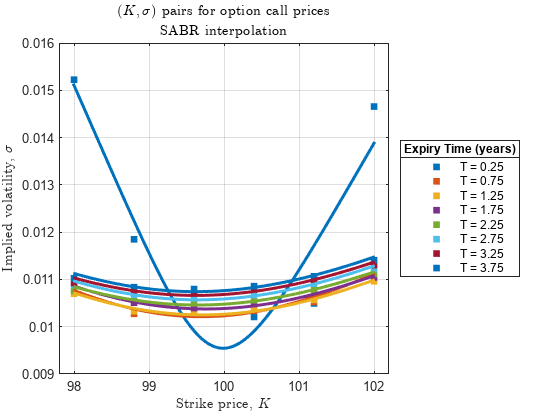

figure
gscatter(D.K, D.SigmaCall, D.T)
hold on
for k = 1:numel(T0)
    plot(fineK, sigmaCallSABR(:, k), "LineWidth", 2, "Color", cols(k, :))
end % for
xlabel("Strike price, $K$", "Interpreter", "latex")
ylabel("Implied volatility, $\sigma$", "Interpreter", "latex")
title("$(K, \sigma)$ pairs for option call prices", "Interpreter", "latex")
subtitle("SABR interpolation", "Interpreter", "latex")
grid on
lg = legend(legText, "Location", "eastoutside");
title(lg, "Expiry Time (years)")

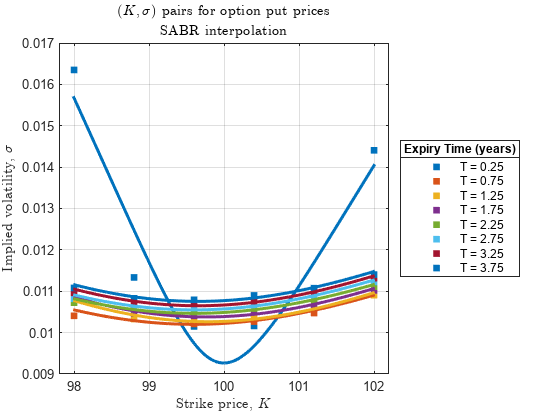


figure
gscatter(D.K, D.SigmaPut, D.T)
hold on
for k = 1:numel(T0)
    plot(fineK, sigmaPutSABR(:, k), "LineWidth", 2, "Color", cols(k, :))
end % for
xlabel("Strike price, $K$", "Interpreter", "latex")
ylabel("Implied volatility, $\sigma$", "Interpreter", "latex")
title("$(K, \sigma)$ pairs for option put prices", "Interpreter", "latex")
subtitle("SABR interpolation", "Interpreter", "latex")
grid on
lg = legend(legText, "Location", "eastoutside");
title(lg, "Expiry Time (years)")

## Transform the data from volatility to option price space.

After interpolation in $(K, \sigma)$ space, either via cubic splines, SABR interpolation, or some other method, we obtain enough data points to estimate the implied strike price density functions at each expiry time.

We begin by converting the $(K, \sigma)$ pairs into $(K, C)$ (respectively, $(K, P)$) space.

Preallocate space for the option prices.

newC = NaN(size(sigmaCallSABR));
newP = NaN(size(sigmaPutSABR));

Extract the scalar asset price and risk-free rate values.

S = D.S(1);
rf = D.rf(1);

Evaluate the new option prices over the interpolated strike price values using the Black-Scholes model ([`blsprice`](matlab: doc blsprice)).

for k = 1:numel(T0)    
    newC(:, k) = blsprice(S, fineK, rf, T0(k), sigmaCallSABR(:, k));
    newP(:, k) = blsprice(S, fineK, rf, T0(k), sigmaPutSABR(:, k));
end % for

## Estimate the implied densities by approximating derivatives.

Approximate the first derivatives of the option prices, $\frac{\partial C}{\partial K}$ and $\frac{\partial P}{\partial K}$ at each distinct expiry time. We use the discrete approximation to the first derivative.

dK = diff(fineK);
Cdash = diff(newC) ./ dK;
Pdash = diff(newP) ./ dK;

Approximate the second derivatives $\frac{\partial^2C}{\partial K^2}$ and $\frac{\partial^2P}{\partial K^2}$ of the option prices with respect to the strike prices.

d2K = dK(2:end);
Cddash = diff(Cdash) ./ d2K;
Pddash = diff(Pdash) ./ d2K;

## Use the approximate derivatives to estimate each density function.

Preallocate space for the PDF approximations.

approxCallPDFs = NaN(size(Cddash));
approxPutPDFs = NaN(size(Pddash));

We remove any negative values prior to the estimation process. Set any negative values to zero.

Cddash(Cddash < 0) = 0;
Pddash(Pddash < 0) = 0;
for k = 1:width(Cddash)
    approxCallPDFs(:, k) = exp(rf * T0(k)) * Cddash(:, k);    
    approxPutPDFs(:, k) = exp(rf * T0(k)) * Pddash(:, k);
end % for

## Plot the density functions approximated using this technique.

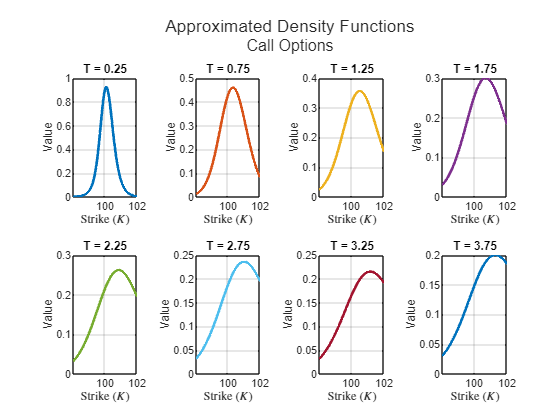

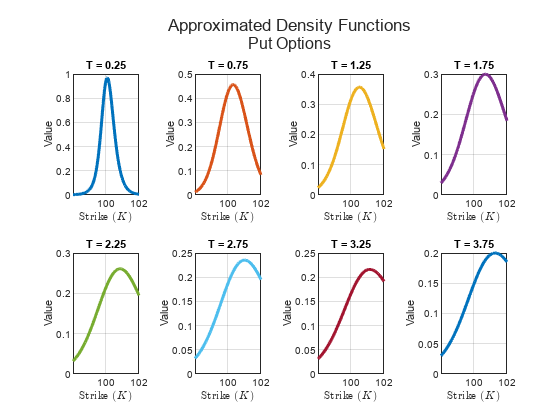

pdfK = fineK(3:end);

figure
tl1 = tiledlayout(2, 4);
title(tl1, "Approximated Density Functions")
subtitle(tl1, "Call Options")

figure
tl2 = tiledlayout(2, 4);
title(tl2, "Approximated Density Functions")
subtitle(tl2, "Put Options")

for k = 1:width(approxCallPDFs)
    
    % Update the call option density plot.
    nexttile(tl1)
    plot(pdfK, approxCallPDFs(:, k), "LineWidth", 2, "Color", cols(k, :))
    xlabel("Strike $(K)$", "Interpreter", "latex")
    ylabel("Value")
    title("T = " + num2str(T0(k)))
    grid on

    % Repeat for the put option density plot.
    nexttile(tl2)
    plot(pdfK, approxPutPDFs(:, k), "LineWidth", 2, "Color", cols(k, :))
    xlabel("Strike $(K)$", "Interpreter", "latex")
    ylabel("Value")
    title("T = " + num2str(T0(k)))
    grid on

end % for

## Fit interpolants to each approximated function.

Use the `fit` function in Curve Fitting Toolbox to fit linear interpolants to each approximated density function.

pdfFitsCall = cell(1, width(approxCallPDFs));
pdfFitsPut = cell(1, width(approxPutPDFs));

for k = 1:numel(T0)
    pdfFitsCall{k} = fit(pdfK, approxCallPDFs(:, k), "linear");
    pdfFitsPut{k} = fit(pdfK, approxPutPDFs(:, k), "linear");
end % for

## Normalize and visualise the pdfs estimated by interpolation.

Define a suitable range of strike price values for the interpolation.

fitKCall = linspace(min(D.K)-4, max(pdfK)+6, 5000).';

Preallocate space for the interpolated PDFs.

fitKCall = repmat({fitKCall}, 1, numel(pdfFitsCall));
fitKPut = fitKCall;
fitValsCall = cell(1, numel(pdfFitsCall));
fitValsPut = fitValsCall;

Use a loop to perform the interpolation and create a visualization of the PDFs for each unique expiry time.

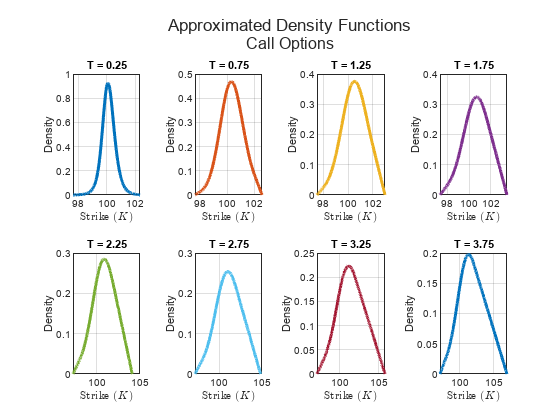

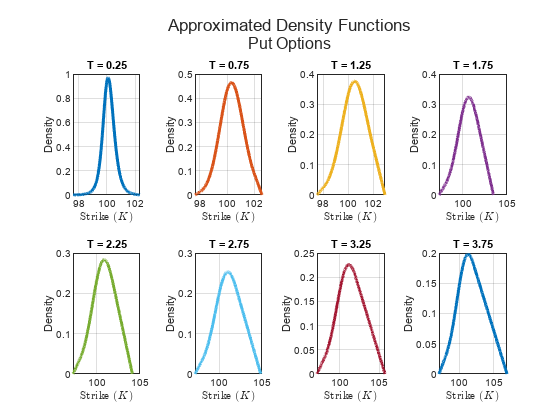

figure
tl1 = tiledlayout(2, 4);
title(tl1, "Approximated Density Functions")
subtitle(tl1, "Call Options")

figure
tl2 = tiledlayout(2, 4);
title(tl2, "Approximated Density Functions")
subtitle(tl2, "Put Options")

for k = 1:numel(pdfFitsCall)
    
   
    
    % Evaluate the fits.
    fitValsCall{k} = pdfFitsCall{k}(fitKCall{k});
    fitValsPut{k} = pdfFitsPut{k}(fitKPut{k});
    
    % Truncate the distribution to ensure positive PDF values.
    posIdx = fitValsCall{k} >= 0;
    fitKCall{k} = fitKCall{k}(posIdx);
    fitValsCall{k} = fitValsCall{k}(posIdx);
    posIdx = fitValsPut{k} >= 0;
    fitKPut{k} = fitKPut{k}(posIdx);
    fitValsPut{k} = fitValsPut{k}(posIdx);
    
    % Ensure the area under the curve is 1.
    A = trapz(fitKCall{k}, fitValsCall{k});
    fitValsCall{k} = fitValsCall{k} / A;
    A = trapz(fitKPut{k}, fitValsPut{k});
    fitValsPut{k} = fitValsPut{k} / A;    

    % Plot the density functions.     
    nexttile(tl1)
    plot(fitKCall{k}, fitValsCall{k}, "Color", cols(k, :), "LineWidth", 2)
    xlabel("Strike $(K)$", "Interpreter", "latex")
    ylabel("Density")
    title("T = " + num2str(T0(k)))
    grid on

    nexttile(tl2)
    plot(fitKPut{k}, fitValsPut{k}, "Color", cols(k, :), "LineWidth", 2)
    xlabel("Strike $(K)$", "Interpreter", "latex")
    ylabel("Density")
    title("T = " + num2str(T0(k)))
    grid on

end % for

## Randomly sample from the distributions defined by these densities.

For each unique expiry time, randomly sample from the distributions defined by the estimated density functions.

numSamples = 1e3;
priceSimCall = NaN(numel(pdfFitsCall), numSamples);
priceSimPut = priceSimCall;
for k = 1:numel(T0)
    priceSimCall(k, :) = randsample(fitKCall{k}, numSamples, true, fitValsCall{k});
    priceSimPut(k, :) = randsample(fitKPut{k}, numSamples, true, fitValsPut{k});
end % for

## Create the fan charts.

Define $T = 0$ initially.

historical = [0, S];
forecastCall = [T0, priceSimCall];
forecastPut = [T0, priceSimPut];

First, create a fan chart from the call option price data using the [`fanplot`](matlab: edit fanplot) function.

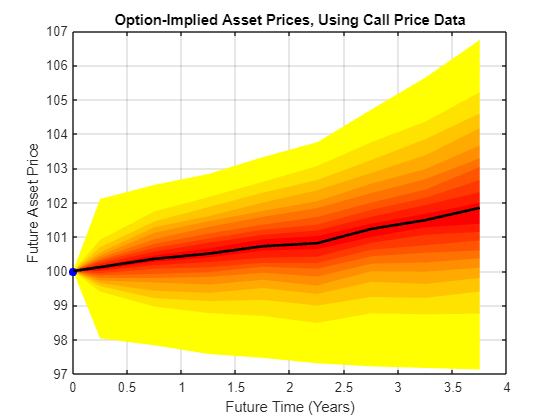

fanplot(historical, forecastCall)
thresh = [3, 7];
ylim([S-thresh(1), S+thresh(2)])
xlabel("Future Time (Years)")
ylabel("Future Asset Price")
title("Option-Implied Asset Prices, Using Call Price Data")

Next, create a fan chart from the put option price data.

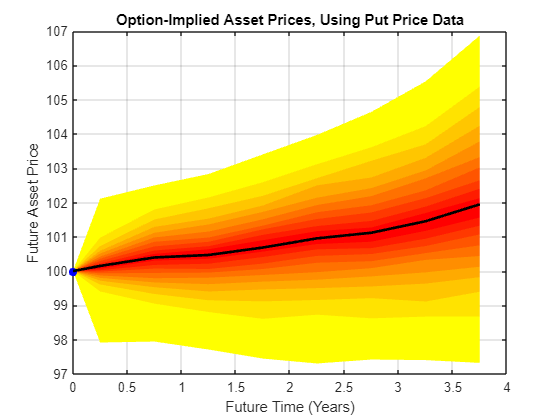

fanplot(historical, forecastPut)
ylim([S-thresh(1), S+thresh(2)])
xlabel("Future Time (Years)")
ylabel("Future Asset Price")
title("Option-Implied Asset Prices, Using Put Price Data")

Show the average forecast.

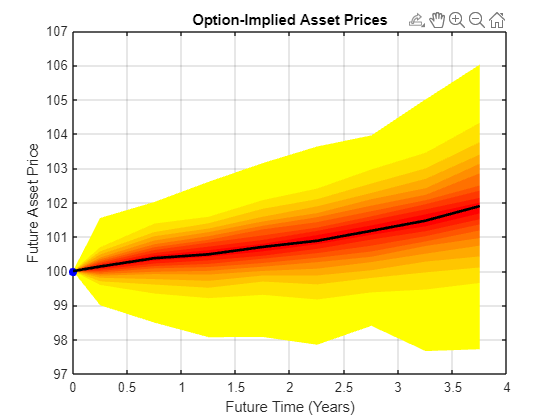

avgForecast = (forecastCall + forecastPut)/2;
fanplot(historical, avgForecast)
ylim([S-thresh(1), S+thresh(2)])
xlabel("Future Time (Years)")
ylabel("Future Asset Price")
title("Option-Implied Asset Prices")